## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_ = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

Set up **backtestPortfolio** **Method **properties

none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)       **NOTE**: z_target options 'mean' or 'latest'

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

## 3. Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

CC = 1; % no constraint if == 1
W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class1 = backtestedPortfolios;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'rolling_w';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index);
test_class1.WinsorStd = W_sd;
test_class1.CashConstriant = CC;
test_class1.RegLambda = 0.00;
% test_class1.PSRbenchmark = "strategyWise";

test_backtestObject = OOPbacktest_analysis(test_class1);
test_backtestObject.Attributions

%%% Create storage for simulation objects
configurationMatrix  = linspace(0, 1, 15);
num_configs = length(configurationMatrix);
simulationCellArray = cell(1, num_configs);
%%% Create storage for the cummulative performance curves 

ans = 5×5 table
                   Ann.Return    Ann.Risk      SR       Ann.SR      PSR  
                   __________    ________    _______    ______    _______

    EW              0.10758      0.096754    0.13531    1.6581    0.94756
    MV              0.12879        0.1464    0.12712    1.5715     0.9386
    BalFun (BH)     0.11233       0.10081    0.14216    1.7454    0.95624
    HRP             0.11301       0.10794    0.13451    1.6519    0.94439
    BalFun (CM)     0.11143      0.094951    0.14845     1.822    0.96211


for config = 1:num_configs  
    % test_class1.CashConstriant = configurationMatrix(config);
    test_class1.WinsorStd = configurationMatrix(config);
    % test_class1.RegLambda = configurationMatrix(config);
    %%% Run backtest
    simulationCellArray{config} = OOPbacktest_analysis(test_class1); 
end

% Create a new figure for the plot
figure('InnerPosition', [100, 100, 600, 600]);
% Iterate through each timetable in the cell array and plot it
for i = 1:numel(simulationCellArray)
    subplot(1, 1, 1);  % Define the subplot layout as needed
    plot(simulationCellArray{i}.RollingPerformance.Time, simulationCellArray{i}.RollingPerformance.("HRP"));  % Adjust VariableName1 as needed
    hold on;
    i;% Overlay plots on the same axes
end
% Customize the plot as needed
title(['Varying Winsorise std. Exclusively: ',num2str(num_configs), ' Trails'],'FontSize', 16);
xlabel('Time','FontSize', 15);
ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed

BCKTST_SIM_Performance_plot = gcf;

% Release hold so that future plots won't overlay
hold off; 

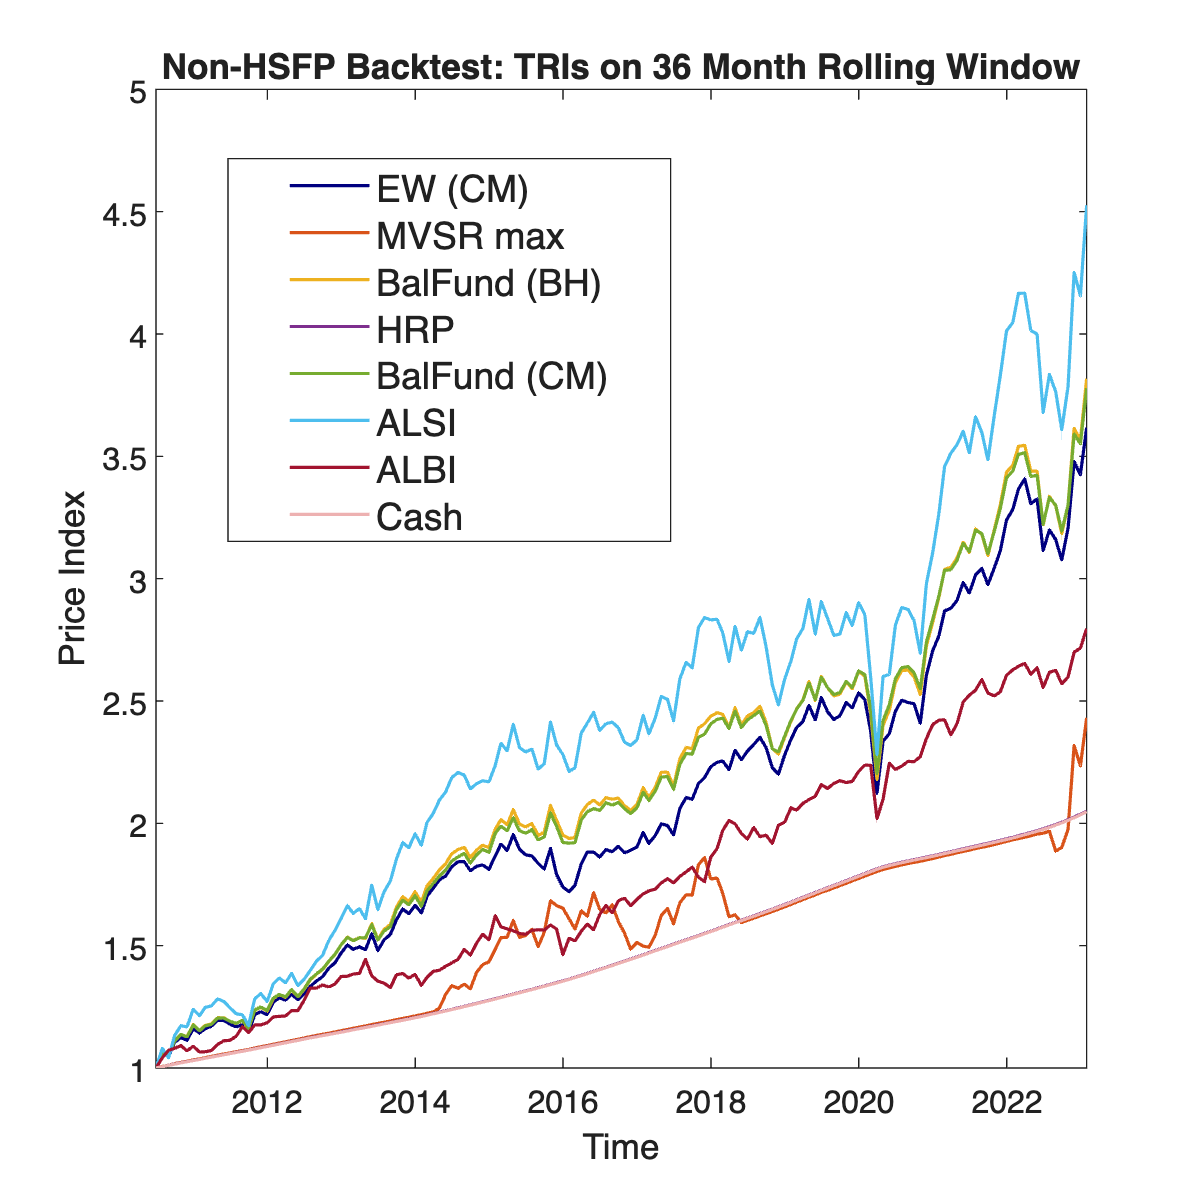

% test_class1.CashConstriant = 0.8; 
test1_bcktest = OOPbacktest_analysis(test_class1);
test1_bcktest.HSFPparameters;
PerformancePlot(test1_bcktest);

test1_bcktest.Attributions

ans = 5×5 table
                   Ann.Return    Ann.Risk        SR       Ann.SR       PSR  
                   __________    _________    ________    _______    _______

    EW               0.10758      0.096754     0.13531     1.6581    0.99976
    MV              0.073167      0.088174    0.045029    0.54376    0.99965
    BalFun (BH)      0.11233       0.10081     0.14216     1.7454    0.99979
    HRP             0.058684     0.0034962      0.1677     2.0125          1
    BalFun (CM)      0.11143      0.094951     0.14845      1.822    0.99988


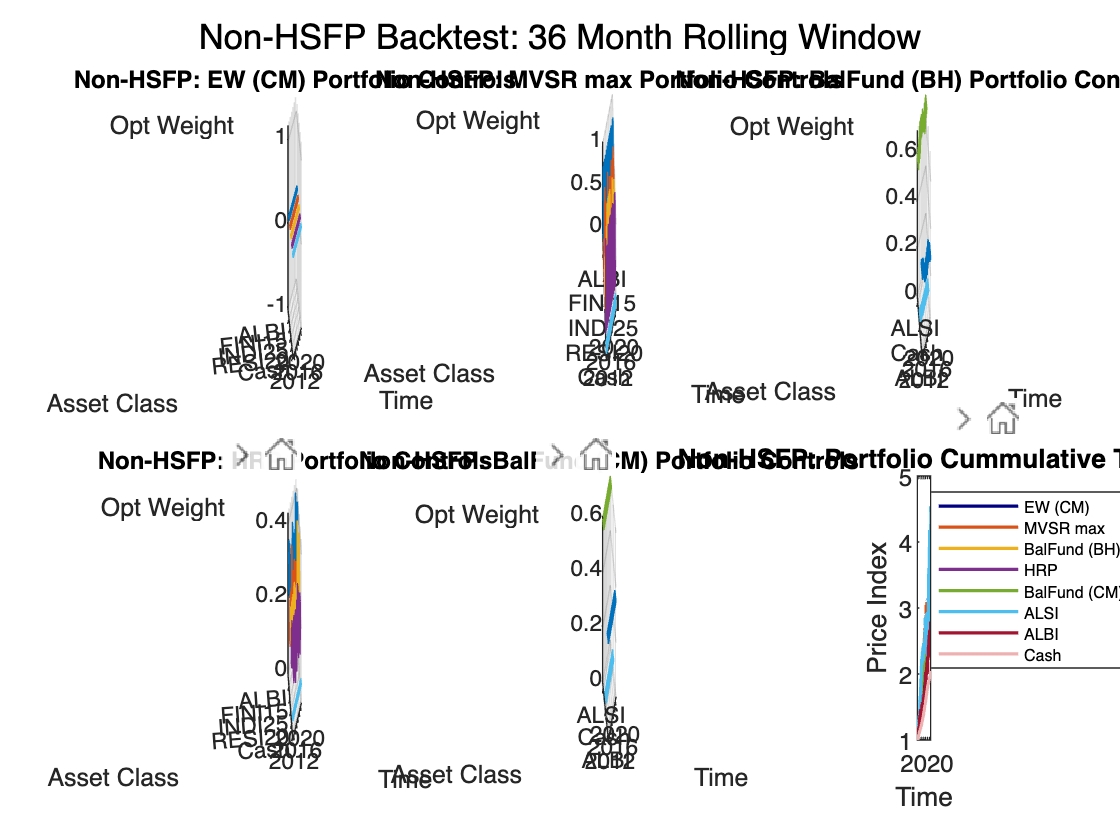

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


OptControlPlot(test1_bcktest)

Y = test1_bcktest.RollingPerformance.Time;
Z = [test1_bcktest.OptPortWts{2,4}];
h = ribbon(Y,Z,0.5);
title(['Optimal Weight Surfaces for ',test1_bcktest.OptPortWts{1,4},' Portfolio'],'FontSize', 16 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
h(1).EdgeColor = "white";
h(2).EdgeColor = "white";
h(3).EdgeColor = "white";
h(4).EdgeColor = "white";
h(5).EdgeColor = "white";
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])

test1_bcktest.Attributions

ans = 5×5 table
                       Ann.Return             Ann.Risk                SR                 Ann.SR                PSR       
                   __________________    __________________    _________________    ________________    _________________

    EW              0.107578483174024    0.0967536780611385    0.135313655942721    1.65805447095177    0.999764415114968
    MV             0.0675932437788258    0.0234132889371539    0.105448416372483    1.27033584083431    0.999999999999997
    BalFun (BH)     0.112330735406128     0.100809256669074    0.142161271621354    1.74542369873731    0.999792845342653
    HRP            0.0970268718793554    0.0815147152666622    0.126758923935962    1.54636365893303    0.999632564332669
    B

## **WINSOREISED** RETURNS

CC = 1; % no constraint if == 1
W_sd = 2; % exclude if no winsorising is wanted
test_class2 = backtestedPortfolios;
HSFPparameters_test = HSFPparameters;
test_class2.HSFPparameters = HSFPparameters_test;
test_class2.WinsorStd = W_sd;
test_class2.Returns = M_Ret_TT;
test_class2.Method =  'none';
test_class2.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class2.CashConstriant = CC;
test_class2.RegLambda = 0.005;

 test2_bcktest = OOPbacktest_analysis(test_class2)

test2_bcktest =   backtestedPortfolios with properties:

        PortfoliosList: {'EW (CM)'  'MVSR max'  'BalFund (BH)'  'HRP'  'BalFund (CM)'  'ALSI'  'ALBI'  'Cash'}
             AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'Cash'}
          Attributions: [5×5 table]
    RollingPerformance: [152×8 timetable]
              HSFP_Prs: []
         NumPortfolios: 0
              DataType: "backtestedPortfolios"
         ExcessReturns: [151×5 double]
           GeometricSR: [1.9534 1.5124 1.9619 2.0138 2.0690]
            OptPortWts: {2×5 cell}
    Realised_tsPRet_TT: [152×8 timetable]
          WindowLength: 36
               Returns: [188×6 timetable]
               Signals: [189×1 timetable]
             RegLambda: 0.0050
             WinsorStd: 2
              MVWts_lb: [0 0 0 0 0]
              MVWts_ub: [1 1 1 1 1]
        CashConstriant: 1
                Method: "none"
        H

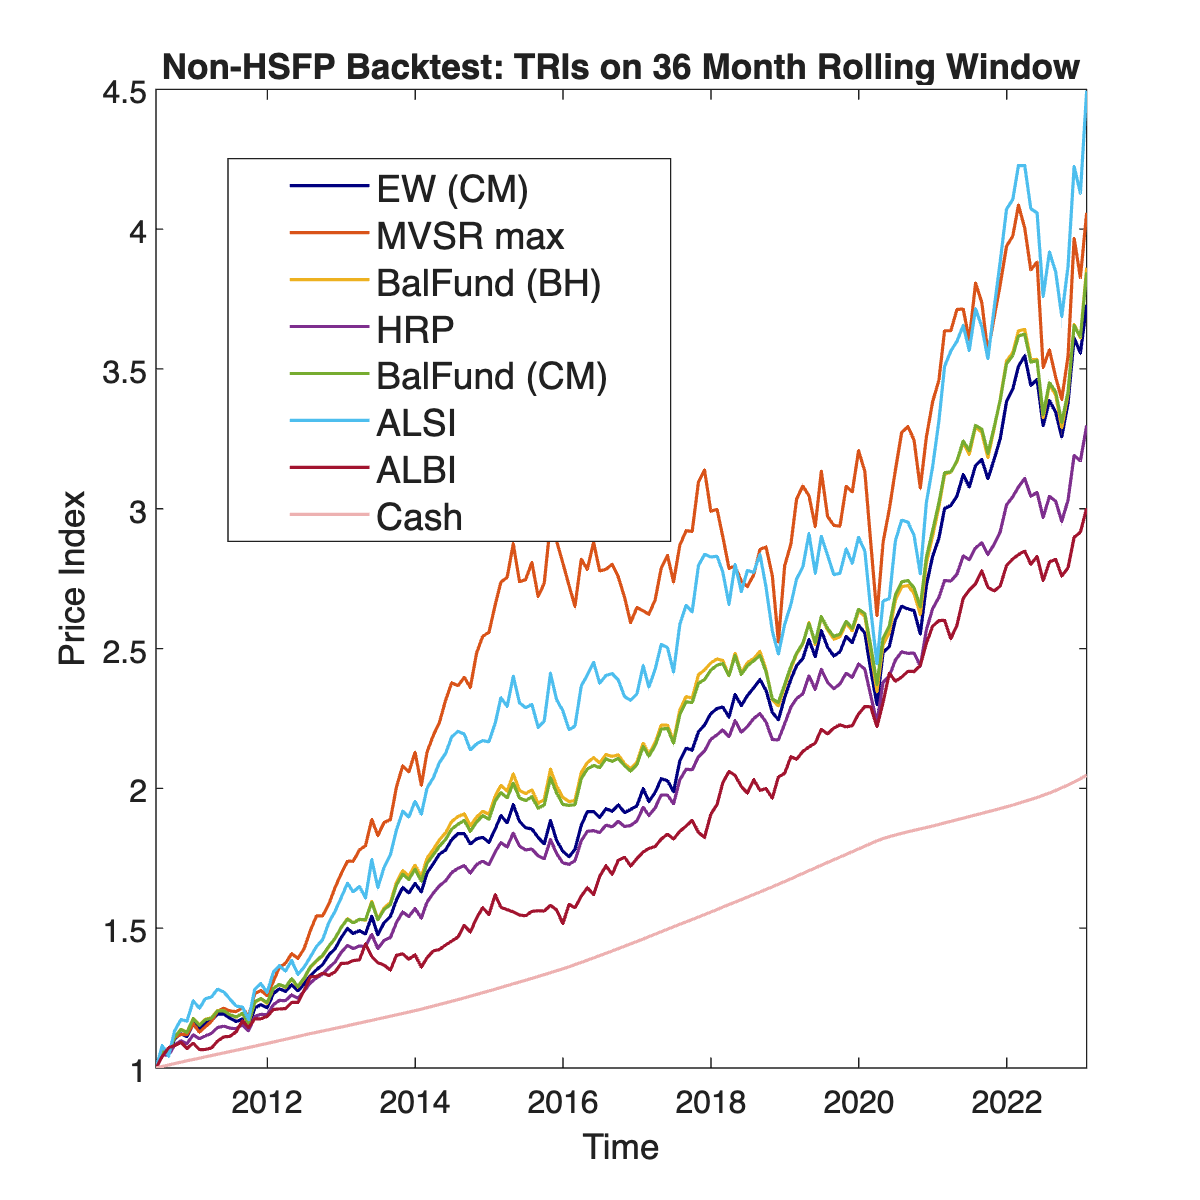

PerformancePlot(test2_bcktest);

test2_bcktest.Attributions

[0.001, 0.003, 0.005, 0.008, 0.01, 0.02]

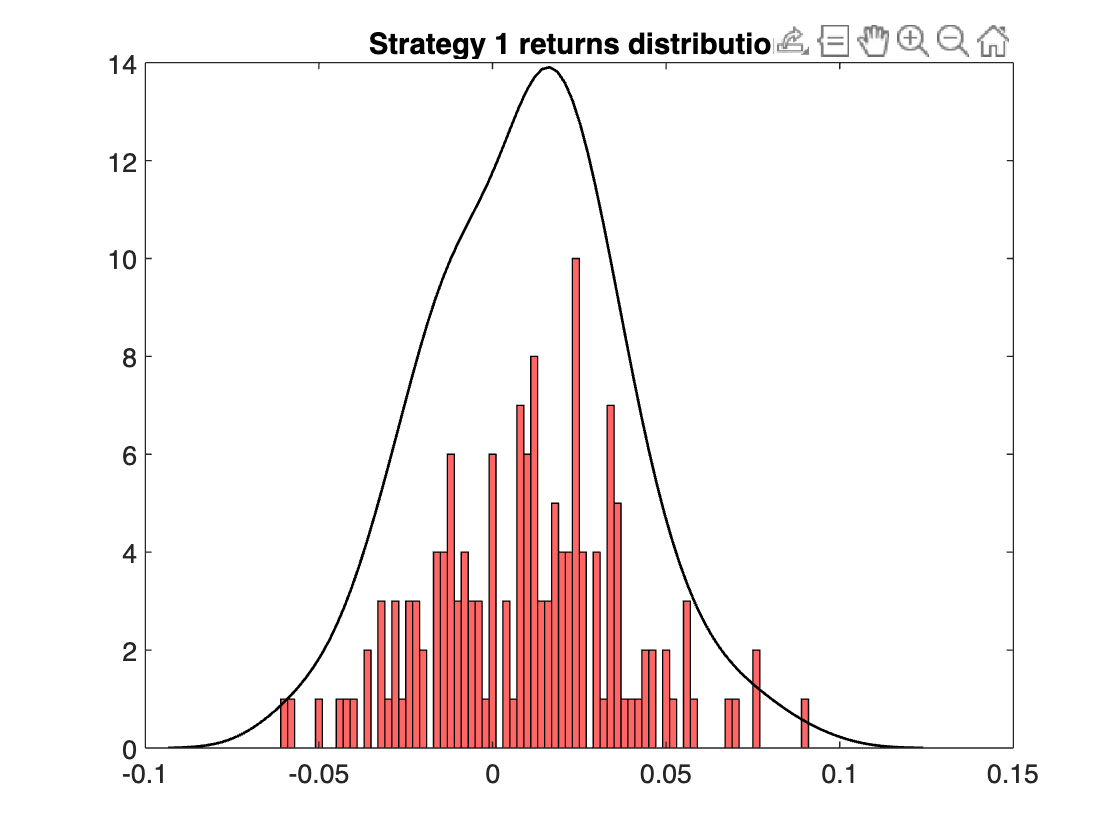

returns_st1 = test2_bcktest.Realised_tsPRet_TT.HRP; 
SIZE = numel(returns_st1);

% Create a histogram
histogram(returns_st1, SIZE/2, 'FaceColor', 'red');
title('Strategy 1 returns distribution');

% Overlay the kernel density estimate
hold on;
[f, xi] = ksdensity(returns_st1);
plot(xi, f, 'LineWidth', 1, 'Color', 'k');
hold off;